## Phase 4: Optimization and inertia ellipsoid of manipulator

From the code of the previous phase, the DH parameters can be inferred as

%{
L1 = 96.78; L2 = 129.794; L3 = 112.268; L4 = 10;
...
T01 = dh_transform(theta1, 0, 0, 0);
T12 = dh_transform(theta2, 0, L1 - 90, 90);
T23 = dh_transform(theta3, 0, L2 + 4, 0);
T3EE = dh_transform(0, 0, L4-7, 0);
...
%}
function T = dh_transform(theta, d, a, alpha)
    theta = deg2rad(theta); alpha = deg2rad(alpha);
    T = [cos(theta), -sin(theta), 0, a;
         sin(theta)*cos(alpha), cos(theta)*cos(alpha), -sin(alpha), -d*sin(alpha);
         sin(theta)*sin(alpha), cos(theta)*sin(alpha), cos(alpha), d*cos(alpha);
         0, 0, 0, 1];
end


The total length of a manipulator can be calculated as:


$$L=\sum^N_{i=1}(a_{i-1}+d_i)$$


In this case, the total length of the a full extended linkage is in computed as 143.574 mm. Based on the context of the design in previous phases, the workplace volume is constrained based on joint range of linkage.Joint 1's angle range is between $-90^\circ$ and $90^\circ$. Joint 2's range range is between $0^\circ$ and $135^\circ$. Joint 3's angle range is between $-45^\circ$ and $135^\circ$. 

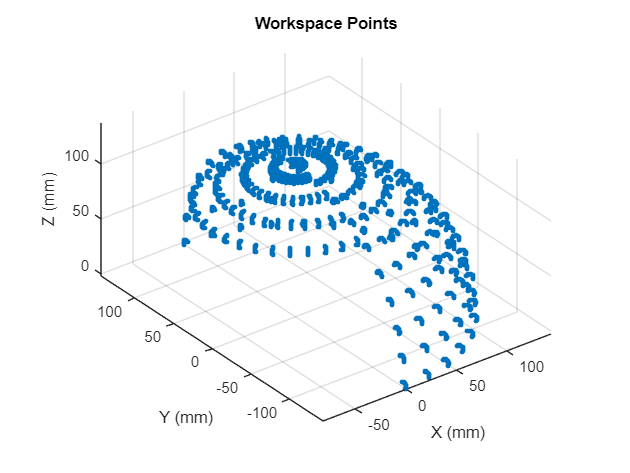

%% DH parameters
% From your previous calculation
% joint | theta | d | a | alpha
% J1: theta1, d=0, a=0, alpha=0
% J2: theta2, d=0, a=6.78, alpha=90
% J3: theta3, d=0, a=133.794, alpha=0
% EE: theta=0, d=0, a=3, alpha=0

a1 = 0; alpha1=0; d1=0;
a2 = 6.78; alpha2=90; d2=0;
a3 = 133.794; alpha3=0; d3=0;
a4 = 3; alpha4=0; d4=0; % EE link

%% Joint limits (deg)
theta1_range = -90:10:90;   % sweep horizontally
theta2_range = 0:10:135;    % shoulder
theta3_range = -45:10:135;  % elbow

%% Collect all end-effector positions
points = [];

for theta1 = theta1_range
    for theta2 = theta2_range
        for theta3 = theta3_range
            % Compute forward kinematics using DH
            T01 = dh_transform(theta1, d1, a1, alpha1);
            T12 = dh_transform(theta2, d2, a2, alpha2);
            T23 = dh_transform(theta3, d3, a3, alpha3);
            T34 = dh_transform(0, d4, a4, alpha4); % EE

            T = T01 * T12 * T23 * T34;

            % End-effector position
            pos = T(1:3,4)';
            points(end+1,:) = pos;
        end
    end
end

%% Plot workspace
figure; scatter3(points(:,1), points(:,2), points(:,3), 10, 'filled');
xlabel('X (mm)'); ylabel('Y (mm)'); zlabel('Z (mm)');
title('Workspace Points'); axis equal; grid on; view(3);

%% Compute convex hull volume
% Convert mm to m
points_m = points / 1000;
[K, volume] = convhull(points_m(:,1), points_m(:,2), points_m(:,3));

fprintf('Estimated workspace volume: %.4f m^3 (%.1f cm^3)\n', volume, volume*1e6);

Estimated workspace volume: 0.0041 m^3 (4066.3 cm^3)


### Part A

Goal: Calculate the length sum () and structural length index () of your manipulators.

total_length = (a1+a2+a3+a4 + d1+d2+d3+d4)/1000;
fprintf("Total length of the manipulator: %.4f m\n", total_length);

Total length of the manipulator: 0.1436 m


structural_length_index = total_length./volume^(1/3);
fprintf("Structural length index Q_L: %.4f\n", structural_length_index)

Structural length index Q_L: 0.8995


max_volume = 4/3*pi*total_length.^3;
useable_space = volume./max_volume * 100;
fprintf("Percentage of usable space in reach: %.4f", useable_space);

Percentage of usable space in reach: 32.8008

### Part B

Goal: Determine the optimal value of  for your manipulator. Adjust the links lengths according to your findings

The length of fully extended arm is computed as 0.1436 m and the structural length index are computed as 0.8995. To compute the optimal length, first simplify the overall structure. Based on the previous context, the robot arm has two part: joint 1 create an offset from the ground and Joint 2 and 3 are the 2 linkage robot arm that do all the robotic manipulator's mechanics and Joint 4 is an extension of Joint 3. In short, the robot arm can be simplified into a 2 linkage robot arm with a new Joint 1's length of 6.78 mm and Joint 2's length of 136.794 mm. Assuming the robot arm is optimized to standardized for the same length and mass distribution while keeping the joint's angle the same, the structural length index should be minimized.


$$Q_L=\frac{2L}{\sqrt[3]{4/3*\pi*(2L)^3)}}=\frac{2L}{\sqrt[3]{4/3\pi}*2L}=0.62035$$


The equation can be further generalized and the result are still the same. It implies there is no optimal choice of arm length if minimizing the structural length index is the only criteria for optimization.


$$Q_L(L_1, L_2)=\frac{L_1 + L_2}{\sqrt[3]{4/3*\pi*(L_1 + L_2)^3)}}$$


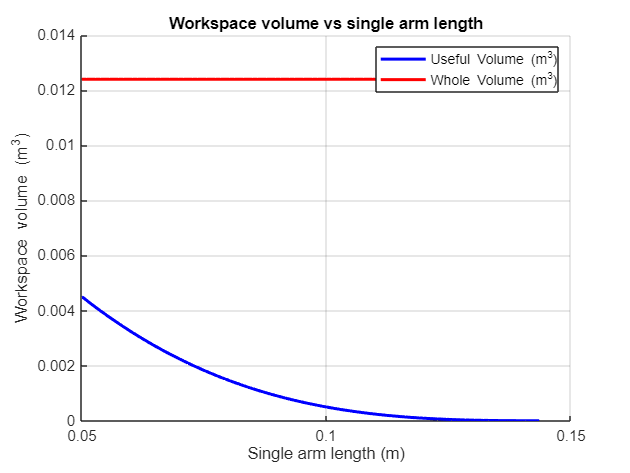

total_length = 0.143574;
link_lengths = linspace(0.05, total_length, 100); % meters
n = size(link_lengths);
volumes = zeros(n);

volume_sphere = @(x,y) (4/3) * pi * (x + y).^3 ;
volume_hallow_sphere = @(x,y) (8/3) * pi * y * (3*x^2 + y^2);
volume_torus = @(x,y) 2*pi^2*x*y;
volume_cylinder = @(x,y) pi*x^2*y;

structural_idx_sphere = zeros(n);
structural_idx_hallow_sphere = zeros(n);
structural_idx_torus = zeros(n);
structural_idx_cylinder = zeros(n);
index = 0;

for i = link_lengths
    j = total_length-i;
    index = index + 1;
    volumes(index) = compute_volume(j,j);
    structural_idx_sphere(index) = total_length/(nthroot(volume_sphere(i,j), 3));
    structural_idx_hallow_sphere(index) = total_length/(nthroot(volume_hallow_sphere(i,j), 3));
    structural_idx_torus(index) = total_length/(nthroot(volume_torus(i,j), 3));
    structural_idx_cylinder(index) = total_length/(nthroot(volume_cylinder(i,j), 3));
end

figure;
hold on
plot(link_lengths, volumes, 'b-', 'LineWidth', 2, DisplayName="Useful Volume (m^3)");
plot(link_lengths, volume_sphere(link_lengths, total_length - link_lengths), 'r-', 'LineWidth', 2, DisplayName="Whole Volume (m^3)")
xlabel('Single arm length (m)');
ylabel('Workspace volume (m^3)');
title('Workspace volume vs single arm length');
grid on; legend show; hold off

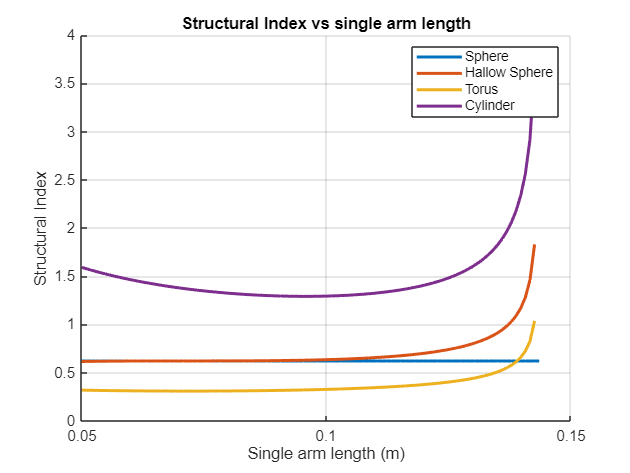


figure;
hold on;
plot(link_lengths, structural_idx_sphere, 'LineWidth', 2, DisplayName="Sphere");
plot(link_lengths, structural_idx_hallow_sphere, 'LineWidth', 2, DisplayName="Hallow Sphere");
plot(link_lengths, structural_idx_torus, 'LineWidth', 2, DisplayName="Torus");
plot(link_lengths, structural_idx_cylinder, 'LineWidth', 2, DisplayName="Cylinder");
xlabel('Single arm length (m)');
ylabel('Structural Index');
title('Structural Index vs single arm length');
grid on; hold off; legend show;

% Optimal length of each setup
[link1, link2, index] = find_minimum_idx(link_lengths, structural_idx_hallow_sphere, total_length);
fprintf("Minimum SLI of a hallow sphere: %.4f with link 1 = %.4f and link 2 = %.4f\n", index, link1, link2);

Minimum SLI of a hallow sphere: 0.6147 with link 1 = 0.0500 and link 2 = 0.0936


[link1, link2, index] = find_minimum_idx(link_lengths, structural_idx_torus, total_length);
fprintf("Minimum SLI of a torus: %.4f with link 1 = %.4f and link 2 = %.4f\n", index, link1, link2);

Minimum SLI of a torus: 0.3076 with link 1 = 0.0717 and link 2 = 0.0718


[link1, link2, index] = find_minimum_idx(link_lengths, structural_idx_cylinder, total_length);
fprintf("Minimum SLI of a cylinder: %.4f with link 1 = %.4f and link 2 = %.4f\n", index, link1, link2);

Minimum SLI of a cylinder: 1.2904 with link 1 = 0.0954 and link 2 = 0.0482



function [length, other_length, minimum] = find_minimum_idx(links_length, idx, total_length)
    minimum = min(idx);
    index = idx == minimum;
    length = links_length(index);
    other_length = total_length - length;
end

% Compute workspace volume using convex hull
function volume = compute_volume(link_length1, link_length2)
    %% Joint limits (degrees)
    theta1_range = -90:10:90;   % base rotation
    theta2_range = 0:10:135;    % shoulder
    theta3_range = -45:10:135;  % elbow

    %% Collect end-effector positions
    points = [];

    for theta1 = theta1_range
        for theta2 = theta2_range
            for theta3 = theta3_range
                % Compute forward kinematics (using DH parameters)
                % angles in degrees, dh_transform uses cosd/sind
                T01 = dh_transform(theta1, 0, 0, 0);
                T12 = dh_transform(theta2, 0, link_length1, 90);
                T23 = dh_transform(theta3, 0, link_length2, 0);
                T34 = dh_transform(0, 0, 0.003, 0); % EE

                % Final transformation
                T = T01 * T12 * T23 * T34;

                % End-effector position
                pos = T(1:3,4)';
                points(end+1,:) = pos;
            end
        end
    end

    %% Compute convex hull volume (m^3)
    [~, volume] = convhull(points(:,1), points(:,2), points(:,3));
end

### Part C

Goal: Restrict your manipulator's motion to planar movement (choose the plane) and delineate the workspace boundaries.

As mentioned above the simplification of the robot arm's structure, the critical part of the arm will be taken for this planar analysis: Joint 1's length of 6.78 mm and Joint 2's length of 136.794 mm. To keep thing simple, the plane of this analysis is the XZ plane. On the right half plane, the radius of the arm can extend a maximum of about 150 mm. On the left half plane, the radius is reduced to about 80 mm, however, it has an additional condition which is an elevation of 100 mm. The right half plane is a more interesting subject to study since that is where the workspace is actually used to pick and place test tubes.

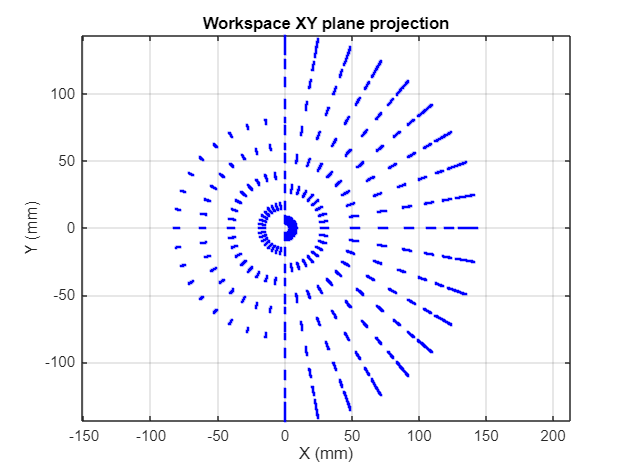

figure;
plot(points(:,1), points(:,2), 'b.', 'MarkerSize', 5); % X vs Y
xlabel('X (mm)');
ylabel('Y (mm)');
title('Workspace XY plane projection');
axis equal;  % keep aspect ratio correct
grid on;

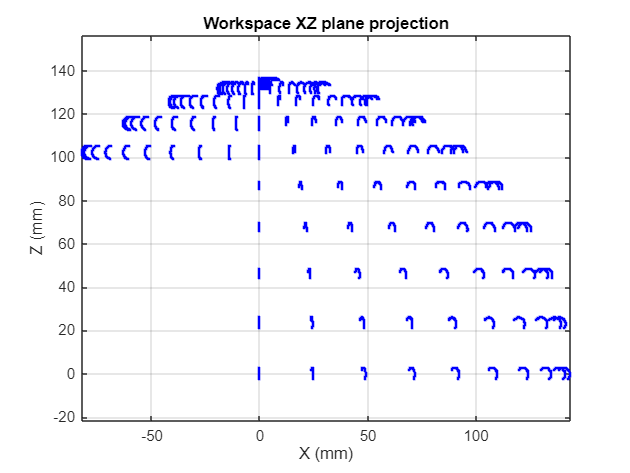

figure;
plot(points(:,1), points(:,3), 'b.', 'MarkerSize', 5); % X vs Y
xlabel('X (mm)');
ylabel('Z (mm)');
title('Workspace XZ plane projection');
axis equal;  % keep aspect ratio correct
grid on;

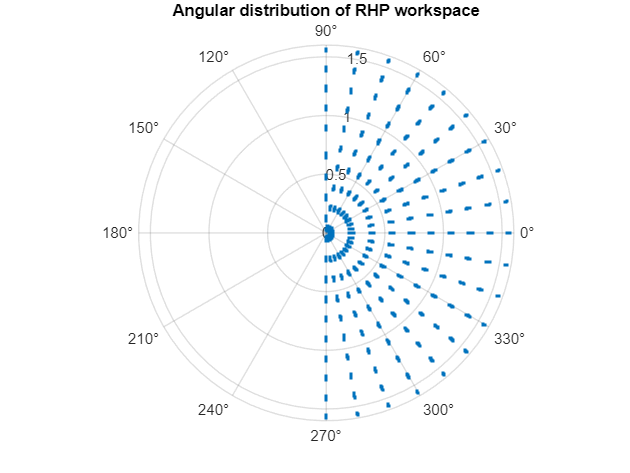

% Logical index where x>0 and z>0
idx = (points(:,1) > 0) & (points(:,3) > 0);

% Keep only those points
points_rhp = points(idx,:);
x = points_rhp(:,1);
y = points_rhp(:,2);
z = points_rhp(:,3);

% radius
r = sqrt(x.^2 + y.^2 + z.^2);

% inclination angle theta: [0, pi]
theta = acos(z ./ r);

% azimuth angle phi: [-pi, pi]
phi = atan2(y, x);

figure;
polarplot(phi, theta, '.');
title('Angular distribution of RHP workspace');

### Part D

Goal: Employ Asada's method to plot the inertia ellipsoids for your manipulator for the planar case in part C.

The ellipsoids closer to the base of the arm seem smaller and more circular, meaning more uniform and generally high dexterity. Ones that are further away from the origin are more skewed and elongated, represent a non-ideal path for precise control due to multiple mechanical constraints, such as joints' limited angle range and inertia. This is a normal behavior to a robot arm: in a closer working range, the control-ability and dexterity of the arm got significantly increases.

There is a concern that many skewed and elongated ellipsoids are placed near to round and small ellipsoid where X is positive and Y is approaching negative. This means the safe operating zone is further limited to avoid the more deformed ellipsoids.

Overall, the graphs looks physically consistent and meaningful. It visualized both the reachable workspace and the dynamic properties (inertia ellipsoids) of the manipulator, providing more insights about limitations on motions and operating regions for the robot arm.

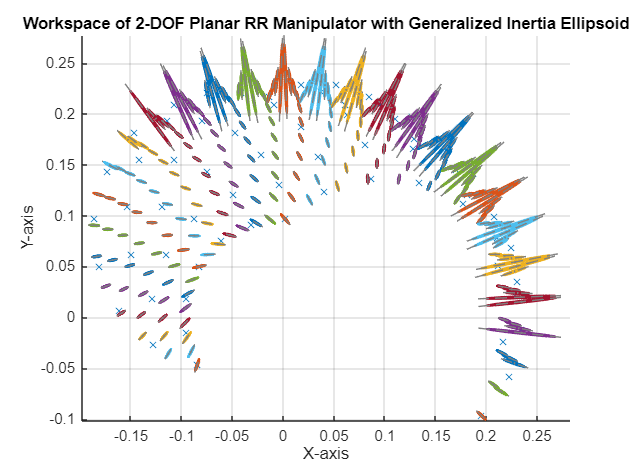

% Parameters
L1 = 98.5/1000;  % Length of the first link (m)
L2 = 136.794/1000;  % Length of the second link (m)
g1 = 105.48/1000; % Center of mass distance from the first joint (m)
g2 = 62.65/1000; % Center of mass distance from the second joint (m)
m1 = 108.74/1000;   % Mass of the first link (kg)
m2 = 36.51/1000;   % Mass of the second link (kg)
I1 = 48797.36*1e-9;    % Moment of inertia of the first link (kg*m^2)
I2 = 3726.42*1e-9;    % Moment of inertia of the second link (kg*m^2)

T1_range = deg2rad(0:20:135);   % shoulder
T2_range = deg2rad(-45:20:135); % elbow

% Initialize workspace points
X = [];
Y = [];

% Compute forward kinematics and workspace
for theta1 = T1_range
    for theta2 = T2_range
        x = L1 * cos(theta1) + L2 * cos(theta1 + theta2);
        y = L1 * sin(theta1) + L2 * sin(theta1 + theta2);
        X = [X, x];
        Y = [Y, y];
    end
end

% Plot workspace
figure;
scatter(X, Y, 'x');
xlabel('X-axis');
ylabel('Y-axis');
title('Workspace of 2-DOF Planar RR Manipulator with Generalized Inertia Ellipsoid');
grid on;
axis equal;
hold on;

% Function to plot the GIE at a specific configuration
theta1_points = linspace(T1_range(1), T1_range(end), 15);
theta2_points = linspace(T2_range(1), T2_range(end), 15);

for theta1 = theta1_points
    for theta2 = theta2_points
        plotGIE(theta1, theta2, L1, L2, m1, m2, g1, g2, I1, I2);
    end
end

hold off;


function plotGIE(theta1, theta2, L1, L2, m1, m2, g1, g2, I1, I2)
    % Jacobian matrix for a 2-DOF planar RR manipulator
    J = [-L1*sin(theta1) - L2*sin(theta1 + theta2), -L2*sin(theta1 + theta2);
          L1*cos(theta1) + L2*cos(theta1 + theta2),  L2*cos(theta1 + theta2)];
      
    % Mass matrix (inertia tensor)
    M = [I1 + I2 + m1*g1^2 + m2*(L1^2 + g2^2), I2 + m2*L1*g2*cos(theta2);
         I2 + m2*L1*g2*cos(theta2), I2 + m2*g2^2];

    % H1 = I1 + m1*g2^2*L1^2;
    % H2 = I2 + m2*g2^2;
    % H3 = m2*L1*g2*cos(theta1-theta2);
    % H = [H1, H3; H3, H2];
    % M = H;

    % Generalized inertia tensor in Cartesian coordinates
    G = inv(J * inv(M) * J');
    
    % Eigenvalues and eigenvectors for the ellipsoid axes
    [V, D] = eig(G);
    eig_values = diag(D);

    % Plot the manipulability ellipsoid
    theta = linspace(0, 2*pi, 100);
    ellipse = [sqrt(eig_values(1)) * cos(theta); sqrt(eig_values(2)) * sin(theta)];
    transformed_ellipse = V * ellipse/100;
    
    % Position of the end-effector
    x = L1 * cos(theta1) + L2 * cos(theta1 + theta2);
    y = L1 * sin(theta1) + L2 * sin(theta1 + theta2);
    
    plot(transformed_ellipse(1, :) + x, transformed_ellipse(2, :) + y, 'LineWidth', 1.5);
    
    % Plot the short and long diameters
    short_diameter = V(:, 1) * sqrt(eig_values(1)) * 2/80;
    long_diameter = V(:, 2) * sqrt(eig_values(2)) * 2/80;
    
    plot([x - short_diameter(1)/2, x + short_diameter(1)/2], [y - short_diameter(2)/2, y + short_diameter(2)/2], '--', 'Color', [0.5, 0.5, 0.5]);
    plot([x - long_diameter(1)/2, x + long_diameter(1)/2], [y - long_diameter(2)/2, y + long_diameter(2)/2], '--', 'Color', [0.5, 0.5, 0.5]);
end